% Al
Al = 0.1;
% Ga
Ga = 0.8;
% In
In = 0.1;

x = In

x = 0.1000

y = Al/(1-x)

y = 0.1111

syms x y
Eg = 1.519+1.36*y-1.584*x+0.55*x*y+0.22*y*y+0.475*x*x

Eg = 1.5253


% wavelength
lambda = 1.4e-6

lambda = 1.4000e-06

h = 6.62606896e-34;
c = 299792458;
e = 1.6021766208e-19;
Eg0 = h*c/lambda/e

Eg0 = 0.8856


Eg0 = 1.35

Eg0 = 1.3500

Eg0 = 0.7338

Eg0 = 0.7338


yy = solve([Eg==Eg0; x==In; y>=0]);

检查对函数 'solve' 的调用中是否存在不正确的参数数据类型或缺少参数。

In
Al = vpa(yy.y*(1-In))
Ga = 1-Al-In

x=0:0.01:1;
y=0:0.01:1;
[x,y]=meshgrid(x,y);
Eg = 1.519+1.36*y-1.584*x+0.55*x*y+0.22*y*y+0.475*x*x

Eg =    20.1283   20.3523   20.5763   20.8004   21.0244   21.2484   21.4725   21.6965   21.9205   22.1446   22.3686   22.5926   22.8167   23.0407   23.2647   23.4888   23.7128   23.9368   24.1609   24.3849   24.6090   24.8330   25.0570   25.2811   25.5051   25.7291   25.9532   26.1772   26.4012   26.6253   26.8493   27.0733   27.2974   27.5214   27.7454   27.9695   28.1935   28.4175   28.6416   28.8656   29.0897   29.3137   29.5377   29.7618   29.9858   30.2098   30.4339   30.6579   30.8819   31.1060
   20.2530   20.4770   20.7010   20.9251   21.1491   21.3731   21.5972   21.8212   22.0452   22.2693   22.4933   22.7173   22.9414   23.1654   23.3894   23.6135   23.8375   24.0615   24.2856   24.5096   24.7337   24.9577   25.1817   25.4058   25.6298   25.8538   26.0779   26.3019   26.5259   26.7500   26.9740   27.1980   27.4221   27.6461   27.8701   28.0942   28.3182   28.5422   28.7663   28.9903   29.2144   29.4384   29.6624   29.8865   30.1105   30.3345   30.5586   30.7826   31.0066   3

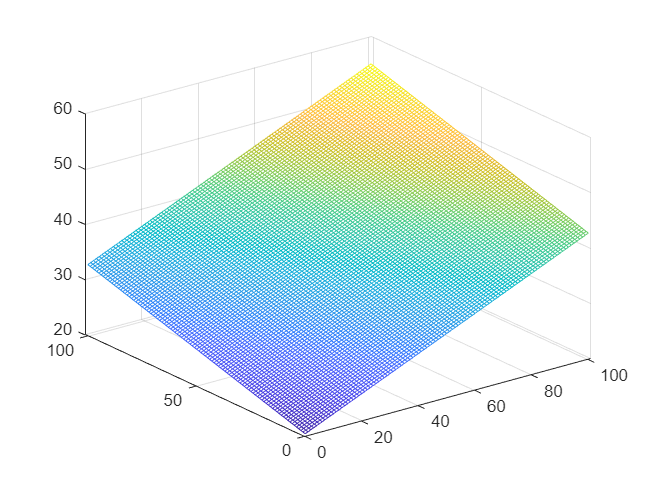

mesh(Eg)